# 2 Zeit diskrete Signale

## 2.2 Faltung

x = [5 4 3 2 1];
u = [1 1 1];

y = faltung(x,u);

## 2.3 Formatierung von Graphen

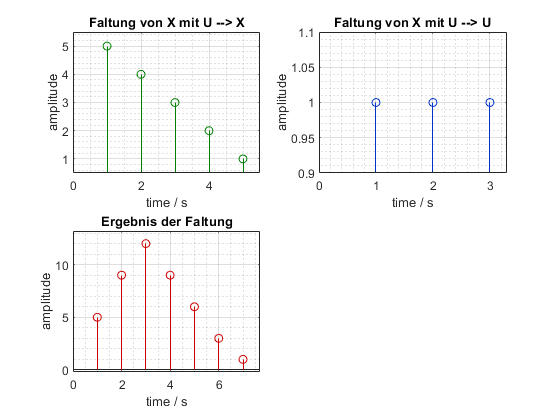

figure (1); 
subplot(2,2,1)
stem(x,'Color',[0 0.5 0])
stem_properties('Faltung von X mit U --> X','time / s','amplitude',x);

subplot(2,2,2)
stem(u,'Color',[0 0.2 0.8])
stem_properties('Faltung von X mit U --> U','time / s','amplitude',u);

subplot(2,2,3)
stem(y,'Color',[0.8 0 0])
stem_properties('Ergebnis der Faltung','time / s','amplitude',y);

## 2.4 Systemeigenschaften

nSymbols = 2^10;
rng(1)
data1 = randn(1, nSymbols);
rng(13)
data2 = randn(1, nSymbols);

dirac_1_pos = floor(length(data1)/2);
dirac = zeros(1, length(data1));
dirac(dirac_1_pos) = 1;

#### Skalierer          y[k] = 2*x[k]

a = 2;
scaled_y1 = scaler(data1, a);
scaled_y2 = scaler(data2, a);

% Linearitätsprüfung (linear = 1)
isequal(scaled_y1 + scaled_y2 , scaler((data1+data2), a))

ans = logical
   1



% Zeitinvarianzprüfung (zeitinvariant = 1)
t0 = 5;
ausgang = circshift(scaled_y1, -t0);
eingang = scaler(circshift(data1, -t0), a);

isequal(ausgang, eingang)

ans = logical
   1



% Kausalitätsprüfung (kausal = 1)
dir_sca = scaler(dirac, a);

for k = 1:length(dir_sca)
    if dir_sca(k)== 1 
        if k < floor(length(dir_sca)/2) 
            kausal = 0
        else 
            kausal = 1
        end
    end
end

#### Offset             y[k] = x[k] + 1

o = 3;
offset_y1 = offset(data1, o);
offset_y2 = offset(data2, o);

% Linearitätsprüfung (linear = 1)
isequal(offset_y1 + offset_y2 , offset((data1+data2), o))

ans = logical
   0



% Zeitinvarianzprüfung (zeitinvariant = 1)
t0 = 5;
ausgang = circshift(offset_y1, -t0);
eingang = offset(circshift(data1, -t0), o);

isequal(ausgang, eingang)

ans = logical
   1



% Kausalitätsprüfung (kausal = 1)
dir_off = offset(dirac, o);

for k = 1:length(dir_off)
    if dir_off(k)== 1 
        if k < floor(length(dir_off)/2) 
            kausal = 0
        else 
            kausal = 1
        end
    end
end

#### Zeitspiegelung    y[k] = x[-k]

mirror_y1 = flip(data1);
mirror_y2 = flip(data2);

% Linearitätsprüfung (linear = 1)
isequal(mirror_y1 + mirror_y2 , flip(data1+data2))

ans = logical
   1



% Zeitinvarianzprüfung (zeitinvariant = 1)
t0 = 5;
ausgang = circshift(mirror_y1, -t0);
eingang = flip(circshift(data1, -t0));

isequal(ausgang, eingang)

ans = logical
   0



% Kausalitätsprüfung (kausal = 1)
dir_mir = flip(dirac);

for k = 1:length(dir_mir)
    if dir_mir(k)== 1 
        if k < floor(length(dir_mir)/2) 
            kausal = 0
        else 
            kausal = 1
        end
    end
end

kausal = 1

#### Differenzenbildung y[k] = x[k]-x[k-1]

diff_y1 = difference(data1);
diff_y2 = difference(data2);

% Linearitätsprüfung (linear = 1)
isequal(diff_y1 + diff_y2 , difference(data1+data2))

ans = logical
   0



% Zeitinvarianzprüfung (zeitinvariant = 1)
t0 = 5;
ausgang = circshift(diff_y1, -t0);
eingang = difference(circshift(data1, -t0));

isequal(ausgang, eingang)

ans = logical
   0



% Kausalitätsprüfung (kausal = 1)
dir_diff = difference(dirac);

for k = 1:length(dir_diff)
    if dir_diff(k)== 1 
        if k < floor(length(dir_diff)/2) 
            kausal = 0
        else 
            kausal = 1
        end
    end
end

kausal = 1

#### Modulation         y[k] = x[k]*cos((pi/4)*k)

mod_y1 = simple_mod(data1);
mod_y2 = simple_mod(data2);

% Linearitätsprüfung (linear = 1)
isequal(mod_y1 + mod_y2 , simple_mod(data1+data2))

ans = logical
   0



% Zeitinvarianzprüfung (zeitinvariant = 1)
t0 = 5;
ausgang = circshift(mod_y1, -t0);
eingang = simple_mod(circshift(data1, -t0));

isequal(ausgang, eingang)

ans = logical
   0



% Kausalitätsprüfung (kausal = 1)
dir_mod = simple_mod(dirac);

for k = 1:length(dir_mod)
    if dir_mod(k)== 1 
        if k < floor(length(dir_mod)/2) 
            kausal = 0
        else 
            kausal = 1
        end
    end
end

kausal = 1

#### Quantisierer       y[k] = gerundet(x[k])

quant_y1 = round(data1);
quant_y2 = round(data2);

% Linearitätsprüfung (linear = 1)
isequal(quant_y1 + quant_y2 , round(data1+data2))

ans = logical
   0



% Zeitinvarianzprüfung (zeitinvariant = 1)
t0 = 5;
ausgang = circshift(quant_y1, -t0);
eingang = round(circshift(data1, -t0));

isequal(ausgang, eingang)

ans = logical
   1



% Kausalitätsprüfung (kausal = 1)
dir_quan = round(dirac);

for k = 1:length(dir_quan)
    if dir_quan(k)== 1 
        if k < floor(length(dir_quan)/2) 
            kausal = 0
        else 
            kausal = 1
        end
    end
end

kausal = 1

## 2.5 FIR-Systeme

coef = [1 2 3 2 1];

fir_system = FIR(x, coef);


